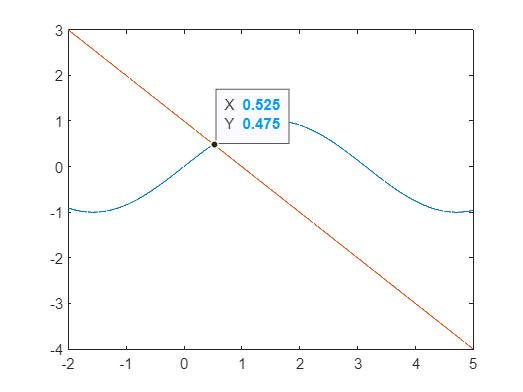

    x_val = -2:0.001:5;
   
    %%nedan en y=sin(x)
    y_values1 = (func1(x_val));
    
 
    plot(x_val,y_values1);
    hold on;
    

     %%nedan en y = 1-x;
    y_values2 = (func2(x_val));
    
   
    %%skärningspunkten mellan sinx och 1-x plottas i övre graf vilket är
    %%markerad
   
    plot(x_val,y_values2);
    ax2 = gca;
    chart2 = ax2.Children(1);
    datatip(chart2,0.525,0.475);
    hold off;

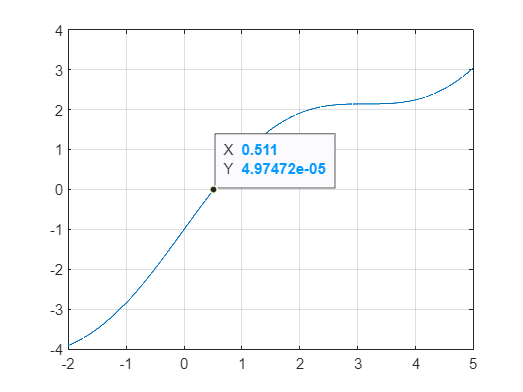

        
    %%nedan sammansatt funktion alltså y=sin(x) + x - 1
    y_values3 = (func3(x_val));
    
    plot(x_val,y_values3);
    
    %%man kan resonera att vid skärningspunkt i övre graf  är de separata
    %%graferna lika med varandra i skärningspunkten alltså kommer den
    %%sammansatta funktionen vara = 0 när båda dessa är lika med varandra
    %%sin(x) + x - 1 = 0
    
    %%newton raphsons metod som räknar ut den andra roten vid ungeför 0,511
    x1 = 0.4  ;%%lämpligt startvärde att börja från 
    for i = 2:-0.0001:0.2
        
        a =  func3(x1);
        b  = func3prim(x1);
        
        x2 = x1  - a/b;
        diff = func3(x2) - func3(x1);
        if  abs(diff) <= tolerance
            
            break;
        end
        x1=x2;
    
    

    end
    %rot markerad i nedre graf
        ax = gca;
    chart = ax.Children(1);
    datatip(chart,x2,func3(x2));




    
        grid on;    

    function y = func1(x)
        
 y = sin(x)  ; 

    end

    function y = func2(x)
        
     y = 1-x;

    end
    
    function y = func3(x)

    y=sin(x) + x - 1;

    end

   function y = func3prim(x)

    y=cos(x) + 1;

    end


    



